% % 6-DoF linear and non-linear models
% syms X_theta_0 X_theta_1s X_delta_e Z_theta_0 Z_theta_1s Z_delta_e M_theta_0 M_theta_1s M_delta_e  % longitudinal stability derivatives
% syms Y_Delta_0_0 Y_theta_1c Y_delta_rud L_Delta_theta_0 L_theta_1c L_delta_rud N_Delta_theta_0 N_theta_1c N_delta_rud
% syms u v w L M N
% syms I_zz I_yy I_xx I_xz X Y Z real
% syms p q r 
% syms phi theta psi
% syms theta_0 theta_1s delta_e   % longitudinal inputs
% syms Delta(theta_0) theta_1c delta_r
% 
% 
% % Longitudinal state vector
% x_lon = [u; w; q; theta]
% 
% % Longitudinal inputs
% u_lon = [theta_0; theta_1s; delta_e]
% 
% % Lateral state vector
% x_lat = [v; p; r; phi; psi]
% 
% % Lateral inputs
% u_lat = [Delta(theta_0); theta_1c; delta_r]

% % Rotational matrices
% %R-ZYX Euler
% Rz = [cos(psi), -sin(psi), 0;
%     sin(psi), cos(psi), 0;
%     0, 0, 1]
% Ry = [cos(theta), 0, sin(theta);
%     0, 1, 0;
%     -sin(theta), 0, cos(theta)]
% Rx = [1, 0, 0;
%     0, cos(phi), -sin(phi);
%     0, sin(phi), cos(phi)]
% 
% % Rotation matrix from body frame to inertial frame
% % R_Euler = Rz*Ry*Rx

% 
% % Longitudinal input matrix
% B_lon = [X_theta_0 X_theta_1s X_delta_e;
%     Z_theta_0 Z_theta_1s Z_delta_e;
%     M_theta_0 M_theta_1s M_delta_e;
%     0 0 0]

% Lateral input matrix
% B_lat = [Y_Delta_0_0 Y_theta_1c Y_delta_rud;
%     L_Delta_theta_0 L_theta_1c L_delta_rud;
%     N_Delta_theta_0 N_theta_1c N_delta_rud;
%      0 0 0;
%      0 0 0]
% 
% % Nominal parameters
% g = 9.81;  % acceleration of free gravity in m/s^2.
% M_a = 3500;  % mass of helicopter in kg
% 
% 
% 
% % System parameters
% 
% % equations of motion
% u_dot = -(w*q - v*r) + (X/M_a) - g*sin(theta);
% v_dot = -(u*r - w*p) + (Y/M_a) - g*cos(theta)*sin(phi);
% w_dot = -(v*p - u*q) + (Z/M_a) - g*cos(theta)*cos(phi);
% % p_dot = ((I_yy - I_zz) * q * r + I_xz*(r_dot + p*q) + L)/I_xx;
% q_dot = ((I_zz - I_xx) * r * p + I_xz*(r^2 - p^2) + M)/I_yy;
% % r_dot = ((I_xx - I_yy) * p * q + I_xz*(p_dot - q*r) + N)/I_zz;
% phi_dot = p + q * sin(phi) * tan(theta) + r * cos(phi) * tan(theta);
% theta_dot = q * cos(phi) - r * sin(phi);
% psi_dot = q*sin(phi)*sec(theta) + r * cos(phi) * sec(theta);
% % 
% % x_dot = [u_dot; v_dot; w_dot; p_dot; q_dot; r_dot; phi_dot; theta_dot; psi_dot];
% x_lon_dot = [u_dot; w_dot; q_dot; theta_dot]
% 
% % u = [theta_0; theta_1s; delta_e; theta_4];
% y_lon_sym = [u; w; q; theta];
% 
% % Longitudinal state space
% A_sym = jacobian(x_lon_dot, x_lon)
% B_lon
% % B_sym = jacobian(x_lon_dot, u_lon)
% % C_sym = jacobian(y_sym, x_lon)
% % D_sym = jacobian(y_sym, u)
% 
% % linear_ss = ss(A_sym, B_sym, C_sym, D_sym)
% % Display equations of motion for inspection
% % fprintf("Equations of motion")
% for i = 1:9
%     disp(eval(['eq', num2str(i)]));
% end

% Hover:
% Position & height over and above the surface (respectively) remains constant
% Rotor RPM is constant
% Heading is constant

## State-space matrices preparation

% Some estimates for the state and control matricies
% Only valid in hover
% Magnitudes may be off
clear
clc
close all

% Final function will look like this with inputs of forward flight speed,
% climb rate etc.
function [A,B,A_lon,B_lon,A_lat,B_lat] = Linearise(x,u)
% Inputs:  x - state vector [u v w p q r phi theta psi]'
%          u - controls vector [theta_0 Delta_theta theta_1c theta_1s delta_r delta_e]'
% Outputs: A - state matrix (9x9)
%          B - Controls matrix (9x6)
%          A_lon - longitudinal states matrix (4x4) [u w q theta]'
%          B_lon - longitudinal controls matrix (4x3) [theta_0 theta_1s delta_e]'
%          A_lat - lateral states matrix (5x5) [v p r phi psi]'
%          B_lat - lateral controls matrix (5x3) [Delta_theta theta_1c delta_r]'


Xu = -0.01;  % change in X-force given a change in u-velocity
Xw = 0.01;  % change in X-force given a change in vertical velocity
Xq = 3.608;  % change in X-force given a change in pitch rate
Zu = 0;  % change in vertical force given a change in u-velocity
Zw = -0.03;  % change in vertical force given a change in w-velocity
Zq = 0;  % change in vertical force given a change in pitch-rate
Mu = 0.01;  % change in pitching moment given a change in u-velocity
Mw = -0.005;  % change in pitching moment given a change in vertical velocity
Mq = -3.75;  % % change in pitching moment given a change in pitch rate
A_lon = [Xu Xw Xq -9.81;
         Zu Zw Zq 0    ;
         Mu Mw Mq 0    ;
         0  0  1  0    ];

Xtheta0 = 9.8;  % change in X-force given a change in average blade pitch
Xtheta1s = -31.1;  % change in X-force given a change in longitudinal cyclic pitch
Ztheta0 = -295.2;  % change in Z-force given a change in average blade pitch
Ztheta1s = 0;  % change in Z-force given a change in longitudinal cyclic pitch
Mtheta0 = 0;  % change in pitching moment given a change in average blade pitch
Mtheta1s = 11;  % change in pitching moment given a change in longitudinal cyclic pitch
B_lon = [Xtheta0 Xtheta1s 0;
         Ztheta0 Ztheta1s 0;
         Mtheta0 Mtheta1s 0;
         0       0        0];

Yv = -0.05;  % change in side force given a change in sideways velocity
Yp = -0.29;  % change in side force given a change in roll rate
Yr = 0;  % change in side force given a change in yaw rate
Lv = -0.01;  % change in rolling moment given a change in lateral velocity
Lp = -7.5;   % change in rolling moment given a change in roll rate
Lr = 0.1;  % change in rolling moment given a change in yaw rate  
Nv = -0.008;  % change in yawing moment given a change in lateral velocity
Np = -1.5;  % change in yawing moment given a change in roll rate
Nr = -0.25;  % change in yawing moment given a change in yaw rate
A_lat = [Yv Yp Yr 9.81 0;
         Lv Lp Lr 0    0;
         Nv Np Nr 0    0;
         0  1  0  0    0;
         0  0  1  0    0];

Ydeltatheta0 = 13.12;  % change in vertical force given a change in average blade pitch
Ytheta1c = -32.8;  % change in vertical force given a change in latitudinal blade pitch
Ldeltatheta0 = 5;  % change in rolling moment given a change in average blade pitch
Ltheta1c = 25;  % change in rolling moment given a change in latitudinal blade pitch
Ndeltatheta0 = -8;  % change in yawing moment given a change in average blade pitch
Ntheta1c = -10;  %  change in yawing moment given a change in latitudinal blade pitch
B_lat = [Ydeltatheta0 Ytheta1c 0;
         Ldeltatheta0 Ltheta1c 0;
         Ndeltatheta0 Ntheta1c 0;
         0            0        0;
         0            0        0];

% These will be filled in on the final version
A = zeros(9,9);
B = zeros(9,6);

end

[~,~,A_lon,B_lon,A_lat,B_lat] = Linearise

A_lon =   -0.010000000000000   0.010000000000000   3.608000000000000  -9.810000000000000
                   0  -0.030000000000000                   0                   0
   0.010000000000000  -0.005000000000000  -3.750000000000000                   0
                   0                   0   1.000000000000000                   0


B_lon = 1.0e+02 *

   0.098000000000000  -0.311000000000000                   0
  -2.952000000000000                   0                   0
                   0   0.110000000000000                   0
                   0                   0                   0


A_lat =   -0.050000000000000  -0.290000000000000                   0   9.810000000000000                   0
  -0.010000000000000  -7.500000000000000   0.100000000000000                   0                   0
  -0.008000000000000  -1.500000000000000  -0.250000000000000                   0                   0
                   0   1.000000000000000                   0                   0                   0
                   0                   0   1.000000000000000                   0                   0


B_lat =   13.119999999999999 -32.799999999999997                   0
   5.000000000000000  25.000000000000000                   0
  -8.000000000000000 -10.000000000000000                   0
                   0                   0                   0
                   0                   0                   0


% 
% evalslon = eig(A_lon);
% figure
% plot(real(evalslon),imag(evalslon),'x');
% 
% evalslat = eig(A_lat);
% figure
% plot(real(evalslat),imag(evalslat),'x')
% Latitudinal and longitudinal outputs
C_lon_att = [
    0 0 0 1];  % output theta
C_lat_att = [0 0 0 1 0;  % output phi & psi
         0 0 0 0 1];

% No feedforward components
D_lon = [0 0 0];
D_lat = [0 0 0;
         0 0 0;];

% Create longitudinal and latitudinal state spaces
heli_ss_lon = ss(A_lon, B_lon, C_lon_att, D_lon);
heli_ss_lat = ss(A_lat, B_lat, C_lat_att, D_lat)


heli_ss_lat =
 
  A = 
           x1      x2      x3      x4      x5
   x1   -0.05   -0.29       0    9.81       0
   x2   -0.01    -7.5     0.1       0       0
   x3  -0.008    -1.5   -0.25       0       0
   x4       0       1       0       0       0
   x5       0       0       1       0       0
 
  B = 
          u1     u2     u3
   x1  13.12  -32.8      0
   x2      5     25      0
   x3     -8    -10      0
   x4      0      0      0
   x5      0      0      0
 
  C = 
       x1  x2  x3  x4  x5
   y1   0   0   0   1   0
   y2   0   0   0   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.



% Assign state names
heli_ss_lon.StateName = {'u-vel'; 'w-vel'; 'pitch rate';
  'pitch angle'};
heli_ss_lat.StateName = {'v-vel'; 'roll rate'; 'yaw rate'; 'roll angle';
    'yaw angle'};

% Assign input variable names
heli_ss_lon.InputName = {'theta_0'; 
                         'theta_1s';
                         'delta_e'};
heli_ss_lat.InputName = {'Delta_theta';
                         'theta_1c';
                         'delta_r'};

% Assign output variable names
heli_ss_lon.OutputName = {'theta'};
heli_ss_lat.OutputName = {'phi'; 'psi'};

% Create transfer functions
heli_tf_lon = tf(heli_ss_lon);
heli_tf_lat = tf(heli_ss_lat);

% Plants 
P_pitch = heli_tf_lon(2)     % longitudinal cyclic pitch to pitch angle


P_pitch =
 
  From input "theta_1s" to output "theta":
             11 s - 0.201
  -----------------------------------
  s^3 + 3.76 s^2 + 0.00142 s + 0.0981
 
Continuous-time transfer function.
Model Properties


% P_avg = heli_tf_lon(1)        % average blade pitch to pitch angle
% P_roll_diff = heli_tf_lat(1, 1)  % rotor pitch difference to roll angle
P_roll_cyc = heli_tf_lat(1, 2)    % lateral cyclic pitch to roll angle


P_roll_cyc =
 
  From input "theta_1c" to output "phi":
            25 s^2 + 6.828 s + 0.3707
  ---------------------------------------------
  s^4 + 7.8 s^3 + 2.41 s^2 + 0.1984 s + 0.03237
 
Continuous-time transfer function.
Model Properties


% P_yaw_cyc = heli_tf_lat(2, 1)     % lateral cyclic pitch to yaw angle


P_yaw_cyc =
 
  From input "Delta_theta" to output "psi":
          -8 s^3 - 68 s^2 - 3.931 s - 1.177
  -------------------------------------------------
  s^5 + 7.8 s^4 + 2.41 s^3 + 0.1984 s^2 + 0.03237 s
 
Continuous-time transfer function.
Model Properties



P_altitude =
 
  From input "theta_0" to output "theta":
                  1.574 s - 0.01182
  --------------------------------------------------
  s^4 + 3.79 s^3 + 0.1142 s^2 + 0.09814 s + 0.002943
 
Continuous-time transfer function.
Model Properties


The transfer function from the average blade pitch to the pitch angle has a positive real-axis zero.

tzero(P_avg({'theta'}, 'theta_0'))

ans =    0.007509529860228


damp(P_avg)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.00e-02                 1.00e+00       3.00e-02         3.33e+01    
  3.27e-03 + 1.61e-01i    -2.03e-02       1.61e-01        -3.06e+02    
  3.27e-03 - 1.61e-01i    -2.03e-02       1.61e-01        -3.06e+02    
 -3.77e+00                 1.00e+00       3.77e+00         2.65e-01    


Similarly, the transfer function from longitudinal cyclic pitch to the pitch angle has a positive real-axis zero.

There is a conjugate pair of poles with a positive real part.

This is important because there is a resonant peak at a frequency of 0.161 rad/s

tzero(P_pitch({'theta'}, 'theta_1s'))

ans =    0.018272727272727


damp(P_pitch)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  3.27e-03 + 1.61e-01i    -2.03e-02       1.61e-01        -3.06e+02    
  3.27e-03 - 1.61e-01i    -2.03e-02       1.61e-01        -3.06e+02    
 -3.77e+00                 1.00e+00       3.77e+00         2.65e-01    


For altitude, there is two zeros: one on the +ve real axis, and one on the -ve real axis.

tzero(P_roll_diff({'phi'}, 'Delta_theta'))

ans =    0.029111478647597
  -0.142871478647597


damp(P_roll_diff)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.88e-02 + 1.23e-01i     1.51e-01       1.24e-01         5.33e+01    
 -1.88e-02 - 1.23e-01i     1.51e-01       1.24e-01         5.33e+01    
 -2.81e-01                 1.00e+00       2.81e-01         3.56e+00    
 -7.48e+00                 1.00e+00       7.48e+00         1.34e-01    


For roll, there are two zeros on the negative real axis.

tzero(P_roll_cyc({'phi'}, 'theta_1c'))

ans =   -0.074761669925475
  -0.198358330074525


damp(P_roll_cyc)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.88e-02 + 1.23e-01i     1.51e-01       1.24e-01         5.33e+01    
 -1.88e-02 - 1.23e-01i     1.51e-01       1.24e-01         5.33e+01    
 -2.81e-01                 1.00e+00       2.81e-01         3.56e+00    
 -7.48e+00                 1.00e+00       7.48e+00         1.34e-01    


## Simple weighting functions for decent tracking, and to limit control bandwidth

### First we start with a simple controller for a simple mode, like Attitude Hold (pitch) (MIXSYN)

% weighting functions using mixsyn

% NOTE THAT USING THE MIXSYN METHOD, WEIGHTS SHOULD BE SET EQUAL TO THE
% RECIPROCAL OF THE DESIRED SHAPES FOR S, KS AND T.
% IN PARTCIULAR:
% %%%
% For good reference-tracking and disturbance-rejection performance, choose W1 large inside the control bandwidth to obtain small S.
% For robustness and noise attenuation, choose W3 large outside the control bandwidth to obtain small T.
% To limit control effort in a particular frequency band, increase the magnitude of W2 in this frequency band to obtain small KS.
% %%%%
% % Tracking and disturbance rejection weight.
% W1 = makeweight(100, 20, 0.01) % high gain at low frequencies, rolls off after that.
% bodemag(W1)
% 
% % Controller effort weight
% W2 = makeweight(30, 1, 0.1);  % low-pass filter to penalise aggressive actuator movements
% 
% % Noise reduction and robustness weight
% W3 = makeweight(0.001, 20, 90); % low gain at high frequencies


% USE MIXSYN FOR MIXED SENSITIVITY LOOP-SHAPING DESIGN
% [K_pitch, CL_pitch, gam_pitch] = mixsyn(P_pitch, W1, W2, W3);


% disp(['Achieved gamma (pitch control): ', num2str(gam_pitch)]);

% % Analyze singular value plots
% figure;
% S_pitch = feedback(1, P_pitch * K_pitch);  % sensitivity function for longitudinal pitch controller
% sigma(P_pitch, 'm', S_pitch, 'b', inv(W1), 'r--'); % S = feedback(1, G*K)
% title('Sensitivity Function');
% legend("Linearised system", "Closed loop", "Inverted controller")
% 
% figure;
% T_pitch = feedback(P_pitch * K_pitch, 1);  % complementary sensitivity function for same controller
% sigma(P_pitch, 'm', T_pitch, 'b', inv(W3), 'r--'); % T = feedback(G*K, 1)
% title('Complementary Sensitivity');
% legend("Linearised system", "Closed loop", "Inverted controller")


## Longitudinal controller (Attitude: pitch)

% Pre-compensator weighting
% Motivation: the input signals to the plant are control signals. We want
% to penalise high actuator effort and aggressive inputs (high frequencies)

% i.e. a low-pass filter
K1 = 1;  % low-pass filter gain
eps_1 = 3;  % filter pole position
W1 = tf(K1, [1, eps_1]);  % integrator chracteristics
% W1 = makeweight(60, 20, 0.05)
% W1 = tf(1, [1, 3]);

% Post-compensator weighting
% Here we design a second-order notch filter 
K2 = 7;   % gain
eps_2 = 37;  % filter pole position
W2 = tf(K2, [1, eps]);

% Design directions for closed-loop control (yet to be quantified)
% Attentuation for gusts assuming gust frequency is 1 <= freq_gust <= 10 (rad/sec)
% Gain margin of at least 6dB for each input-output mapping
% Phase margin of at least 45 degrees for each input-output mapping

% Longitudinal NCFSYN design
% Having seen some negative phase margins, we add a controller of the form
% K = 1 + as
[K_lon, ~, gamma_lon] = ncfsyn(P_pitch, W1, W2);
K_lon = -K_lon;  % invert sign because ncfsyn assumes positive feedback
disp(['Achieved gamma NCFSYN (pitch control): ', num2str(gamma_lon)]);

Achieved gamma NCFSYN (pitch control): 533.0578


long_marigns = allmargin(P_pitch * K_lon)

long_marigns = struct with fields:
     GainMargin: [4.864873549999626 0.359368857991920 1.004240962548911 0.990202640054296 4.180941065202216]
    GMFrequency: [0.098520511516092 0.182021532335493 1.805515596577949 3.813816470174361 17.320633017906111]
    PhaseMargin: [60.535130037064839 -1.555357977722738e+02 0.674605635581869 -0.239360753318523 3.724259248805092]
    PMFrequency: [0.010240219199207 0.139729451601654 1.022841179081416 2.585516567768698 6.672866405294537]
    DelayMargin: [1.031752652669315e+02 25.539165082467921 0.011511161003497 2.428531208118658 0.009741029138231]
    DMFrequency: [0.010240219199207 0.139729451601654 1.022841179081416 2.585516567768698 6.672866405294537]
         Stable: 1


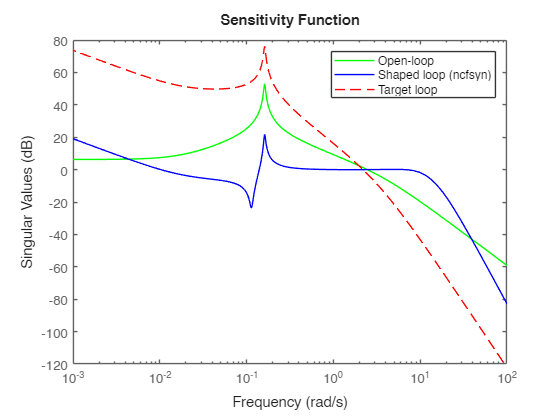

 
% % Analyze singular value plots
figure;
sigma(P_pitch, 'g', P_pitch * K_lon, 'b', W1*P_pitch*W2, 'r--'); 
title('Sensitivity Function');
legend("Open-loop", "Shaped loop (ncfsyn)", "Target loop");

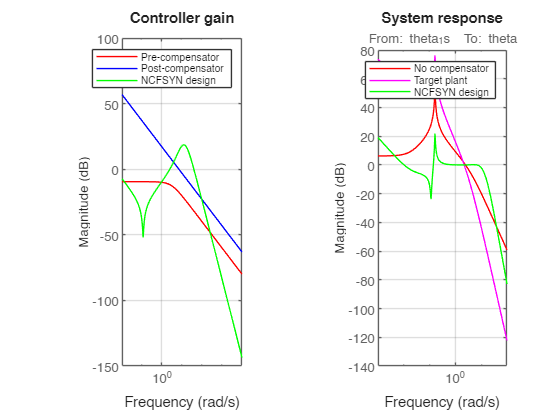


% Controller gain plot
subplot(1, 2, 1)
bodemag(W1, 'r', W2, 'b', K_lon, 'g', {1e-2, 1e4}); grid
legend("Pre-compensator", "Post-compensator", "NCFSYN design")
title("Controller gain")

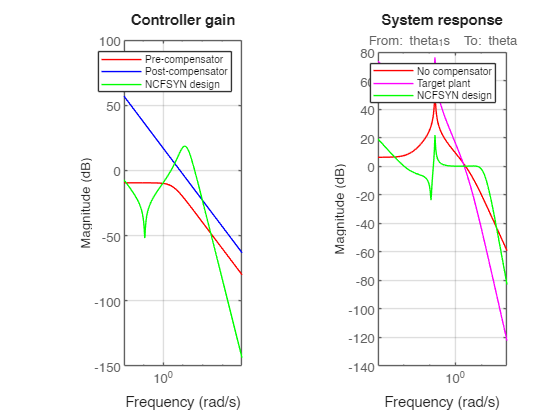


% System frequency response plot
subplot(1, 2, 2)
bodemag(P_pitch, 'r',  W1*P_pitch*W2, 'm', P_pitch*K_lon, 'g', {1e-3, 1e2}); grid
legend("No compensator", "Target plant", "NCFSYN design")
title("System response")

## Lateral controller (Attitude: roll)

% Latitudinal NCFSYN design
[K_lat, ~, gamma_lat] = ncfsyn(P_roll_cyc, W1);
K_lat = -K_lat;
disp(['Achieved gamma NCFSYN (roll control): ', num2str(gamma_lat)]);

Achieved gamma NCFSYN (roll control): 1.637


lat_margins = allmargin(P_roll_cyc * K_lat)

lat_margins = struct with fields:
     GainMargin: 15.362688854498742
    GMFrequency: 6.388997477879355
    PhaseMargin: 79.731822472785751
    PMFrequency: 0.783394192449387
    DelayMargin: 1.776350698254155
    DMFrequency: 0.783394192449387
         Stable: 1


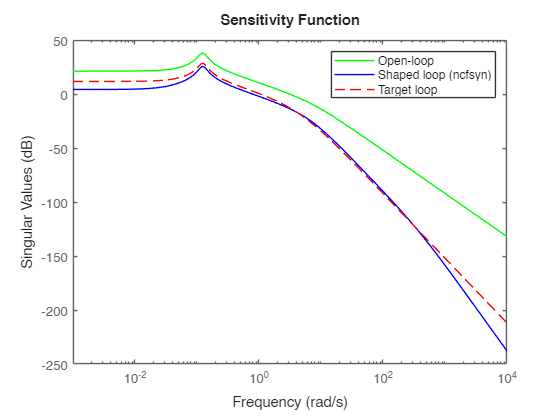


% Analyze singular value plots
figure;
sigma(P_roll_cyc, 'g', P_roll_cyc * K_lat, 'b', P_roll_cyc*W1, 'r--'); 
title('Sensitivity Function');
legend("Open-loop", "Shaped loop (ncfsyn)", "Target loop");

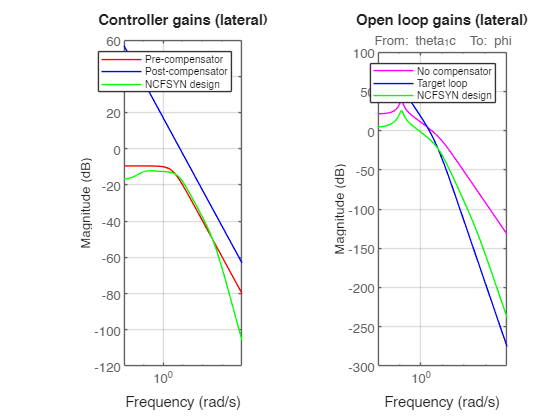


% Controller gain plot
subplot(1, 2, 1)
bodemag(W1, 'r', W2, 'b', K_lat, 'g', {1e-2, 1e4}); grid
legend("Pre-compensator", "Post-compensator", "NCFSYN design")
title("Controller gains (lateral)")

% System frequency response plot
subplot(1, 2, 2)
bodemag(P_roll_cyc, 'm', W1*P_roll_cyc*W2, 'b', P_roll_cyc*K_lat, 'g', {1e-2, 1e4}); grid
legend("No compensator", "Target loop", "NCFSYN design")
title("Open loop gains (lateral)")

## Step and impulse responses

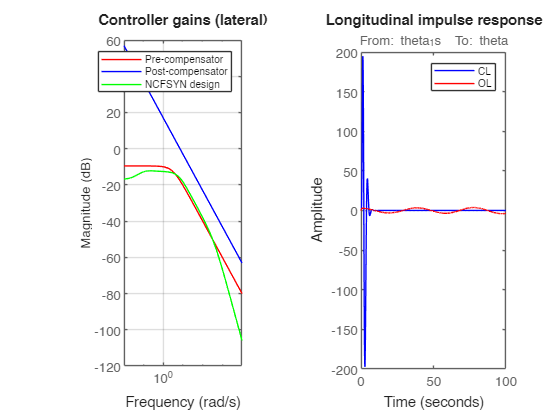

% Responses
impulse(feedback(P_pitch, K_lon), 'b', P_pitch, 'r', 100);
title("Longitudinal impulse response")
legend('CL', 'OL')

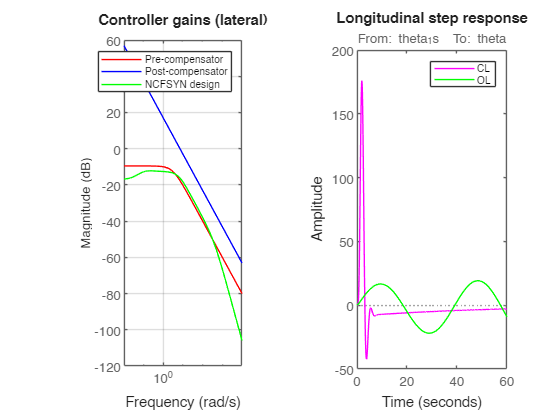

step(feedback(P_pitch, K_lon), 'm', P_pitch, 'g', 60);
title("Longitudinal step response")
legend("CL", "OL")

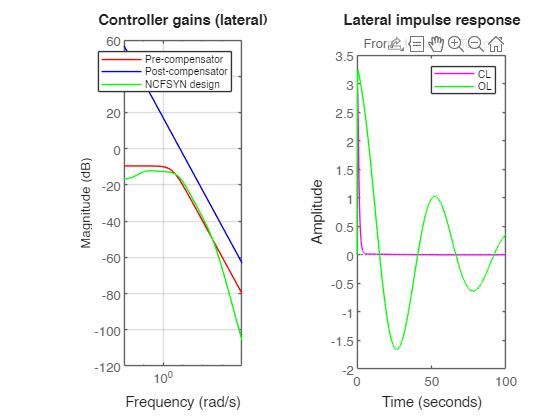


impulse(feedback(P_roll_cyc, K_lat), 'm', P_roll_cyc, 'g', 100);
title("Lateral impulse response")
legend('CL', 'OL')

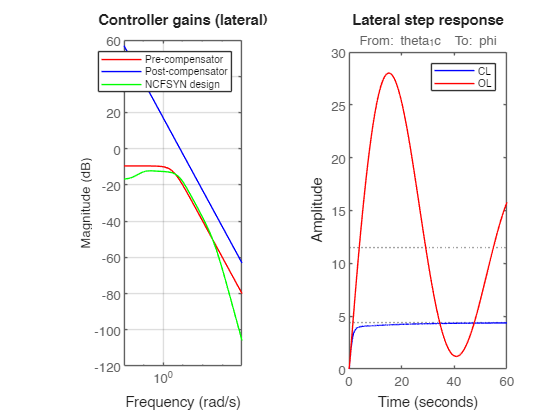

step(feedback(P_roll_cyc, K_lat), 'b', P_roll_cyc, 'r', 60);
title("Lateral step response")
legend("CL", "OL")

size(K_lon)
size(K_lat)